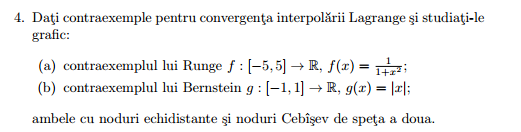

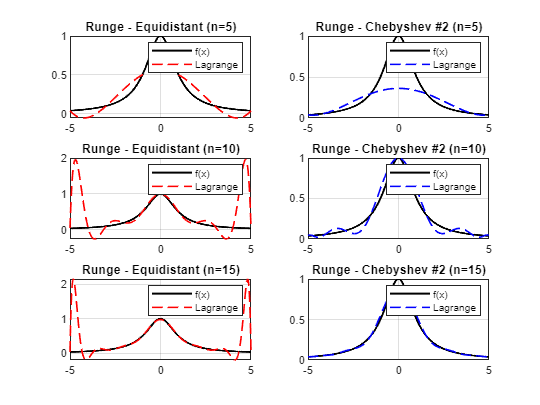

f_runge = @(x) 1 ./ (1 + x.^2);
g_bernstein = @(x) abs(x);

degrees = [5 10 15];
x_runge = linspace(-5, 5, 1000);
x_bernstein = linspace(-1, 1, 1000);

% ======= Runge Counterexample =======
figure;
for i = 1:length(degrees)
    n = degrees(i);
    
    x_eq = linspace(-5, 5, n+1);
    y_eq = f_runge(x_eq);
    y_interp_eq = Lagrange(x_runge, x_eq, y_eq);

    x_cheb = cos((0:n)*pi/n) * (5)';
    x_cheb = sort(x_cheb);
    y_cheb = f_runge(x_cheb);
    y_interp_cheb = Lagrange(x_runge, x_cheb, y_cheb);

    subplot(3,2,2*i-1);
    plot(x_runge, f_runge(x_runge), 'k-', 'LineWidth', 1.5); hold on;
    plot(x_runge, y_interp_eq, 'r--', 'LineWidth', 1.2);
    title(sprintf('Runge - Equidistant (n=%d)', n));
    legend('f(x)', 'Lagrange');
    grid on;

    subplot(3,2,2*i);
    plot(x_runge, f_runge(x_runge), 'k-', 'LineWidth', 1.5); hold on;
    plot(x_runge, y_interp_cheb, 'b--', 'LineWidth', 1.2);
    title(sprintf('Runge - Chebyshev #2 (n=%d)', n));
    legend('f(x)', 'Lagrange');
    grid on;
end

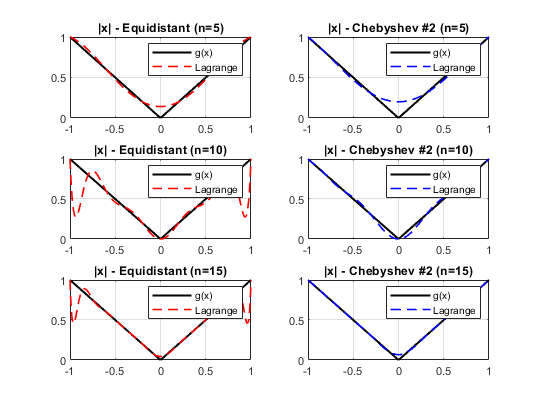


% ======= Bernstein Counterexample =======
figure;
for i = 1:length(degrees)
    n = degrees(i);
    
    x_eq = linspace(-1, 1, n+1);
    y_eq = g_bernstein(x_eq);
    y_interp_eq = Lagrange(x_bernstein, x_eq, y_eq);

    
    x_cheb = cos((0:n)*pi/n);
    x_cheb = sort(x_cheb);
    y_cheb = g_bernstein(x_cheb);
    y_interp_cheb = Lagrange(x_bernstein, x_cheb, y_cheb);

    subplot(3,2,2*i-1);
    plot(x_bernstein, g_bernstein(x_bernstein), 'k-', 'LineWidth', 1.5); hold on;
    plot(x_bernstein, y_interp_eq, 'r--', 'LineWidth', 1.2);
    title(sprintf('|x| - Equidistant (n=%d)', n));
    legend('g(x)', 'Lagrange');
    grid on;

    subplot(3,2,2*i);
    plot(x_bernstein, g_bernstein(x_bernstein), 'k-', 'LineWidth', 1.5); hold on;
    plot(x_bernstein, y_interp_cheb, 'b--', 'LineWidth', 1.2);
    title(sprintf('|x| - Chebyshev #2 (n=%d)', n));
    legend('g(x)', 'Lagrange');
    grid on;
end